## **Part 1**

%---------------------

1. 

Help gives the link for getting started.

Help <directory> shows the contens of the particular directory and the functions therein.

Help clear command depicts the different use of clear.

2.

Initialization of the matrices A, B, C and the variables in the local workspace. After that trace, determinant, rank and trace (using sum(diag)) of each matrices are executed.

i = 3

i =      3

A = magic(i)

A =      8     1     6
     3     5     7
     4     9     2


B = ones(3,1)*(2:4) + zeros(3,3)

B =      2     3     4
     2     3     4
     2     3     4


x = pi/6

x =    0.523598775598299

C = [cos(x) sin(x) 0; -sin(x) cos(x) 0; 0 0 1]

C =    0.866025403784439   0.500000000000000                   0
  -0.500000000000000   0.866025403784439                   0
                   0                   0   1.000000000000000



%Trace
Trace_A = trace (A)

Trace_A =     15

Trace_B = trace (B)

Trace_B =      9

Trace_C = trace (C)

Trace_C =    2.732050807568878


%Determinanat
det_A = det (A)

det_A =   -360

det_B = det (B)

det_B =      0

det_C = det (C)

det_C =      1


%Rank
rank_A = rank (A)

rank_A =      3

rank_B = rank (B)

rank_B =      1

rank_C = rank (C)

rank_C =      3


%Trace using sum(diag)
trace_sum_diag_A = sum(diag(A))

trace_sum_diag_A =     15

trace_sum_diag_B = sum(diag(B))

trace_sum_diag_B =      9

trace_sum_diag_C = sum(diag(C))

trace_sum_diag_C =    2.732050807568878

3.

The following functions depict two different ways to achieve the same output. Matrices are in general not commutative, but they can be multiplied in a different order as long as certain other properties are fulfilled. 

%A + B = B + A ,  A + (B + C) = (A + B) + C

sum_AB = A+B

sum_AB =     10     4    10
     5     8    11
     6    12     6


sum_BA = B+A

sum_BA =     10     4    10
     5     8    11
     6    12     6


sum_A_BC = A+(B+C)

sum_A_BC =   10.866025403784439   4.500000000000000  10.000000000000000
   4.500000000000000   8.866025403784439  11.000000000000000
   6.000000000000000  12.000000000000000   7.000000000000000


sum_AB_C = (A+B)+C

sum_AB_C =   10.866025403784439   4.500000000000000  10.000000000000000
   4.500000000000000   8.866025403784439  11.000000000000000
   6.000000000000000  12.000000000000000   7.000000000000000


%A+B = B+A, A+(B+C) = (A+B)+C are proved.

%(A + B)' = A' + B' , trace(A + B) = trace(A) + trace(B)

transpose_AB = (A+B)'

transpose_AB =     10     5     6
     4     8    12
    10    11     6


transpose_A_B = A'+B'

transpose_A_B =     10     5     6
     4     8    12
    10    11     6


Trace_AB = trace (A+B)

Trace_AB =     24

trace_A_B = trace(A) + trace (B)

trace_A_B =     24

%(A + B)' = A' + B' , trace(A + B) = trace(A) + trace(B) are proved.


%A*(B*C) = (A*B)*C , A*(B + C) = A*B + A*C

multi_A_BC = A*(B*C)

multi_A_BC =    3.480762113533165  53.971143170299740  60.000000000000000
   3.480762113533165  53.971143170299740  60.000000000000000
   3.480762113533165  53.971143170299740  60.000000000000000


multi_AB_C = (A*B)*C

multi_AB_C =    3.480762113533164  53.971143170299740  60.000000000000000
   3.480762113533164  53.971143170299740  60.000000000000000
   3.480762113533164  53.971143170299740  60.000000000000000


multi_sum_A_BC = A*(B+C)

multi_sum_A_BC =   36.428203230275514  49.866025403784434  66.000000000000000
  30.098076211353316  50.830127018922198  67.000000000000000
  28.964101615137757  54.794228634059948  62.000000000000000


multi_sum_AB_BC = A*B + A*C

multi_sum_AB_BC =   36.428203230275507  49.866025403784441  66.000000000000000
  30.098076211353316  50.830127018922191  67.000000000000000
  28.964101615137757  54.794228634059948  62.000000000000000


%A*(B*C) = (A*B)*C , A*(B + C) = A*B + A*C are proved.

%(A*B)' = B'*A' , det(A*C) = det(C*A) = det(A)*det(C)

multi_trans_AB = (A*B)'

multi_trans_AB =     30    30    30
    45    45    45
    60    60    60


multi_trans_B_A = B'*A'

multi_trans_B_A =     30    30    30
    45    45    45
    60    60    60


det_CA = det (C*A)

det_CA =   -360

det_A_C = det (A) * det (C)

det_A_C =   -360

%%(A*B)' = B'*A' , det(A*C) = det(C*A) = det(A)*det(C) are proved.

%trace(A*B)=trace(B*A) , rank(A*B) <= min(rank(A),rank(B))

trace_AB = trace (A*B)

trace_AB =    135

trace_BA = trace (B*A)

trace_BA =    135

rank_A_B = rank (A*B)

rank_A_B =      1

min_rank_A_B = min (rank(A),rank(B))

min_rank_A_B =      1

%trace(A*B)=trace(B*A) , rank(A*B) <= min(rank(A),rank(B)) are proved.

%A-1 * A = eye(3) , (A*C)^-1 = C^-1*A^-1

ainv_A = A^(-1)*A

ainv_A =    1.000000000000000  -0.000000000000000  -0.000000000000000
                   0   1.000000000000000                   0
                   0   0.000000000000000   1.000000000000000


identity_3 = eye(3)

identity_3 =      1     0     0
     0     1     0
     0     0     1


acinv = (A*C)^(-1)

acinv =    0.158053740001598  -0.136203669435530   0.002551623019561
   0.020687336435395  -0.052977213249235   0.123358237066135
  -0.019444444444444   0.188888888888889  -0.102777777777778


cinv_ainv = C^(-1)*A^(-1)

cinv_ainv =    0.158053740001598  -0.136203669435530   0.002551623019561
   0.020687336435395  -0.052977213249235   0.123358237066135
  -0.019444444444444   0.188888888888889  -0.102777777777778


%A-1 * A = eye(3) , (A*C)^-1 = C^-1*A^-1 are proved.

%(A')^-1 = (A^-1)' , det(A^-1) = 1 / det(A)

trans_ainv = (A')^(-1)

trans_ainv =    0.147222222222222  -0.061111111111111  -0.019444444444444
  -0.144444444444444   0.022222222222222   0.188888888888889
   0.063888888888889   0.105555555555556  -0.102777777777778


ainv_trans = (A^(-1))'

ainv_trans =    0.147222222222222  -0.061111111111111  -0.019444444444444
  -0.144444444444444   0.022222222222222   0.188888888888889
   0.063888888888889   0.105555555555556  -0.102777777777778


det_ainv = det (A^-1)

det_ainv =   -0.002777777777778

inv_det_a = 1/ det(A)

inv_det_a =   -0.002777777777778

%(A')^-1 = (A^-1)' , det(A^-1) = 1 / det(A) are proved.

%C'*C = C*C' = eye(3) , C^-1 = C'


For orthonormal matrices, the transpose is equal to the inverse, and the matrix multiplied by its transpose will result in the identity matrix.

mult_ctrans_c = C'*C

mult_ctrans_c =    1.000000000000000  -0.000000000000000                   0
  -0.000000000000000   1.000000000000000                   0
                   0                   0   1.000000000000000


mult_c_ctrans = C*C'

mult_c_ctrans =    1.000000000000000   0.000000000000000                   0
   0.000000000000000   1.000000000000000                   0
                   0                   0   1.000000000000000


eye_3 = eye(3)

eye_3 =      1     0     0
     0     1     0
     0     0     1


cinv = C^(-1)

cinv =    0.866025403784439  -0.500000000000000                   0
   0.500000000000000   0.866025403784439                   0
                   0                   0   1.000000000000000


trans_C = C'

trans_C =    0.866025403784439  -0.500000000000000                   0
   0.500000000000000   0.866025403784439                   0
                   0                   0   1.000000000000000


%C'*C = C*C' = eye(3) , C^-1 = C' are proved.

4.

Testing the property of matrix A which is square. The sum of rows and columns are equal to each other. Also the trace matrix is equal to the sum of individual rows and columns.

sum_A = sum(A)

sum_A =     15    15    15


sum_trans_A = sum(A')

sum_trans_A =     15    15    15


trace_A = trace (A)

trace_A =     15


magic_x = magic (7)

magic_x =     30    39    48     1    10    19    28
    38    47     7     9    18    27    29
    46     6     8    17    26    35    37
     5    14    16    25    34    36    45
    13    15    24    33    42    44     4
    21    23    32    41    43     3    12
    22    31    40    49     2    11    20


sum_magic_x = sum (magic_x)

sum_magic_x =    175   175   175   175   175   175   175


sum_trans_magix_x = sum((magic_x)')

sum_trans_magix_x =    175   175   175   175   175   175   175


trace_magic_x = trace (magic_x)

trace_magic_x =    175

5.

Help size command explains when and how this command is used.

Determining the dimension of the matrix D initialized through D(4,3,2,1)=24. Then size, length and whos command are applied. 

D(4,3,2,1) = 24

D = D(:,:,1) =
     0     0     0
     0     0     0
     0     0     0
     0     0     0
D(:,:,2) =
     0     0     0
     0     0     0
     0     0     0
     0     0    24

Size refers to dimension lengths for a multidimensional array. Here, there are four rows, three columns, and an additional dimension of two values.

size_D = size(D)

size_D =      4     3     2


[m1,m2,m3,m4] = size (D)

m1 =      4

m2 =      3

m3 =      2

m4 =      1

Length refers to the length of a vector. For a multidimentional array, it returns the length of the larger dimension. D is a 4x3x2 matrix.

length_D = length (D)

length_D =      4

whos D displays 4x3x2, which is the number of rows and columns in the matrix D. as well as the allocated bytes (in this case 192) and Class (in this case, double).

whos D

  Name      Size             Bytes  Class     Attributes

  D         4x3x2              192  double              



6.

Manipulation of individual elements of the matrix ( finding the middle, third row, exchanging columns and restoring the original A matrix):

A

A =      8     1     6
     3     5     7
     4     9     2


Setting the first element in the third row to 0:

A(3,1) = 0

A =      8     1     6
     3     5     7
     0     9     2


Exchanging the colums (second comes first, third comes second, first goes last))

A=A(:,[2 3 1])

A =      1     6     8
     5     7     3
     9     2     0


Restoring the original matrices by exchanging the columns once more, and setting the first value in the third row to 2. 

A = A(:,[3 1 2])

A =      8     1     6
     3     5     7
     0     9     2


A(3,1) = 2

A =      8     1     6
     3     5     7
     2     9     2


7.

Separating matrix A by proper indexing into three individual row and three column vectors:

a1j = A(1,:)

a1j =      8     1     6


a2j = A(2,:)

a2j =      3     5     7


a3j = A(3,:)

a3j =      2     9     2


ai1 = A(:,1)

ai1 =      8
     3
     2


ai2 = A(:,2)

ai2 =      1
     5
     9


ai3 = A(:,3)

ai3 =      6
     7
     2


A_restore_row = [a1j;a2j;a3j]

A_restore_row =      8     1     6
     3     5     7
     2     9     2


A_restore_column = [ai1 ai2 ai3]

A_restore_column =      8     1     6
     3     5     7
     2     9     2


8.

Element wise multiplication, division, exponent, etc.

The element-wise operations differ from  matrix operations because they simply operate on the individual elements depending on their position within the matrix. For example, rather than multiplying and summing accross rows and columns, the elementwise multiplication will just multiply together the elements in the (1,1) position of both matrices, to result in the output for the (1,1) position of the new matrix, and so on for the rest of the matrix. 

element_AB = A.*B

element_AB =     16     3    24
     6    15    28
     4    27     8


element_BdivA = B./A

element_BdivA =    0.250000000000000   3.000000000000000   0.666666666666667
   0.666666666666667   0.600000000000000   0.571428571428571
   1.000000000000000   0.333333333333333   2.000000000000000


element_AC = A./C

element_AC =    9.237604307034012   2.000000000000000                 Inf
  -6.000000000000001   5.773502691896257                 Inf
                 Inf                 Inf   2.000000000000000


element_Apower2 = A.^2

element_Apower2 =     64     1    36
     9    25    49
     4    81     4


9.

Solving the linear equation:

y = [28 34 28]'

y =     28
    34
    28



% y = Ax
% x = (A^-1)*y
x = inv (A)* y

x =    1.146496815286624
   2.242038216560510
   2.764331210191083


x_linsolve = linsolve (A,y)

x_linsolve =    1.146496815286624
   2.242038216560510
   2.764331210191083


10 .

Simulating a dataset represented as a column matrix `X` based on three normal distributed random variables and computing mean and standard deviation.

For the first column of random numbers, they were drawn from the standard normal distribution, which centers around 0. This returned a mean of -0.0373 (close to 0), and standard deviation of 0.9664 (close to 1). 

In the second, the mean was changed to 3 and the standard deviation to 4, which is reflected in the resulting mean of 2.6155 and standard deviation of 4.1554.

 In the third column, the standard deviation was changed to 3, which is also reflected in the standard deviation of 2.8984.

X = [randn(100,1) 3+randn(100,1)*4 randn(100,1)*3];
mean_X = mean(X)

mean_X =    0.174613539897200   2.873901784502701   0.589187535209135


std_X = std(X)

std_X =    0.867133447543812   4.384545379804303   2.948259999654436


The maximum value was largest for the second, which centers around 3 and has the largest standard deviation. It was smallest for the first, which centers around 0 and has the smallest standard deviation. 

max_X = max(X)

max_X =    2.596152317592236  11.660722623593246   8.684224390673091


The sum was greatest for the second column vector because although the standard deviation is greatest, there are no negative numbers because it centers around +3. 

The sums were much smaller for the first and second column vectors, which center around 0, with the smallest corresponding to the third vector with a standard deviation of 3.

sum_X = sum(X)

sum_X =    0.174613539897200   2.873901784502701   0.589187535209135


11.

Instead of using built-in function, arithmatic formulas are used to calculate mean and standard deviation and  results are same.

mean_X = sum (X)/ length (X)

mean_X =    0.174613539897200   2.873901784502701   0.589187535209135


sd_X = sqrt(sum(X-ones(100,1)*mean(X).^2)/(length(X)-1))

sd_X =   0.381548746613314 + 0.000000000000000i  0.000000000000000 + 2.332339546478121i  0.494459794571609 + 0.000000000000000i


## Part 2

1.

Clc clears the command window. 

Format long ensures that numbers have 15 digits for double and 7 digits for single. 

Format compact creates a compact layout in the display to make it easier to read. 

Clear removes the variables from the workspace. 

Close closes all figures.

Fclose closes a file. 

clc;
format long;
format compact;
clear;
close all;
fclose all;

2.

The command textread is used to read the text file downloaded from the IERS website, containing earth orientation data from 1962 to today. The command whos, followed by the variable name, provides information about the variable, such as the name, size, class, etc. 

For this dataset, the rows indicate the observations, and the columns indicate the parameters. 

Column names are assigned to the columns in the dataset to make it easier to work with. 


A_dbl = textread('EOP_14_C04_IAU2000A_one_file_1962-now.txt');
whos A_dbl;

  Name           Size              Bytes  Class     Attributes

  A_dbl      21833x16            2794624  double              



[year,month,day,mjd,xpol,ypol,dUT1,LOD,dX,dY,s_xpol,s_ypol, s_dUT1,s_LOD,s_dX,s_dy] = textread('EOP_14_C04_IAU2000A_one_file_1962-now.txt');
clear A_dbl

First, we convert the pole coordinates from arc seconds to meters, and plot them. 

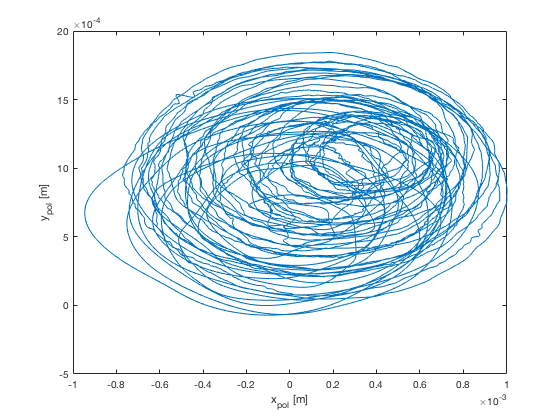

%converts polar coordinates from arc seconds to meters
xpol=xpol./3600.*pi./180.*.6371e+3; %[m]
ypol=ypol./3600.*pi./180.*.6371e+3; %[m]
figure
plot(xpol,ypol)
xlabel('x_{pol} [m]')
ylabel('y_{pol} [m]')

(Figure 2.1: Pole coordinates from IERS)

The next figure shows the celestial pole offset in the x direction over time, and the corresponding standard deviation. The Modified Julian Day is introduced as the x-axis in this plot to indicate how this parameter changes over time.

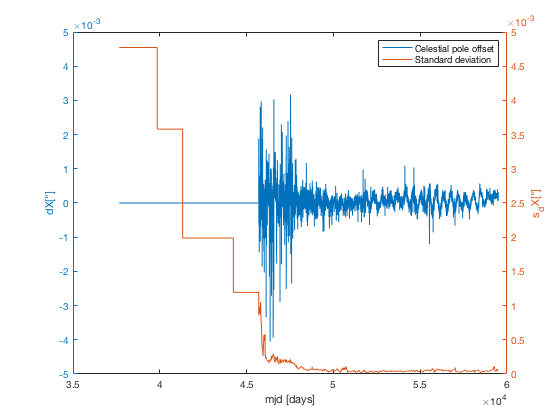


figure
%mjd is modified julian day
[AX,H1,H2]=plotyy(mjd,dX,mjd,s_dX);
xlabel('mjd [days]')
ylabel(AX(1),'dX["]') % left y-axis 
ylabel(AX(2),'s_dX["]') % right y-axis
legend('Celestial pole offset', 'Standard deviation')

(Figure 2.2: Celestial pole offset in x direction from IERS)

The following plot shows the polar motion over time. Adding a time axis (take from the mjd column) makes it easier to interpret visually.

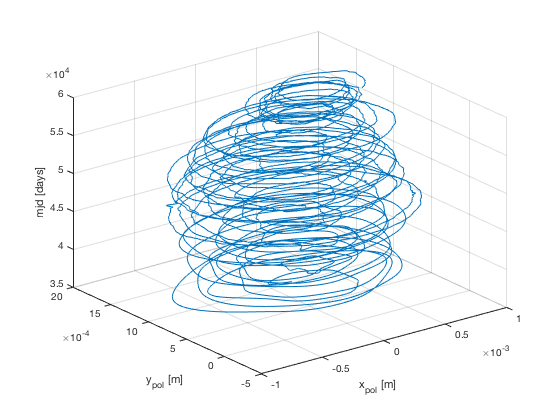

figure
plot3(xpol,ypol,mjd)
xlabel('x_{pol} [m]')
ylabel('y_{pol} [m]')
zlabel('mjd [days]')
grid on

(Figure 2.3: Pole coordinates over time from IERS)

The function comet creates animated plot that changes over the z-axis.

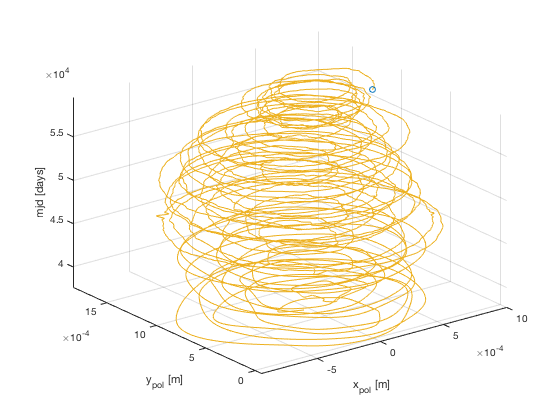

figure
comet3(xpol,ypol,mjd)
xlabel('x_{pol} [m]')
ylabel('y_{pol} [m]')
zlabel('mjd [days]')
grid on

(Figure 2.4: Pole coordinate over time from IERS (with comet function)).

3.

In the next figures, we create histograms depicting a random variable x. With an odd number of bins, the histogram is centered around 0, making it easier to interpret.

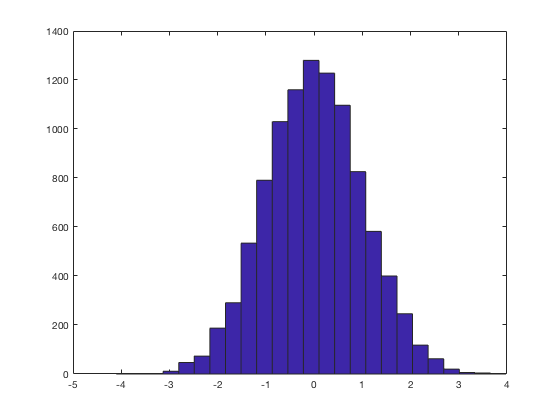

rnd_x = randn(1e+4,1);
figure 
hist(rnd_x,25)

(Figure 3.1: Histogram with random variable x, divided into 25 bins)

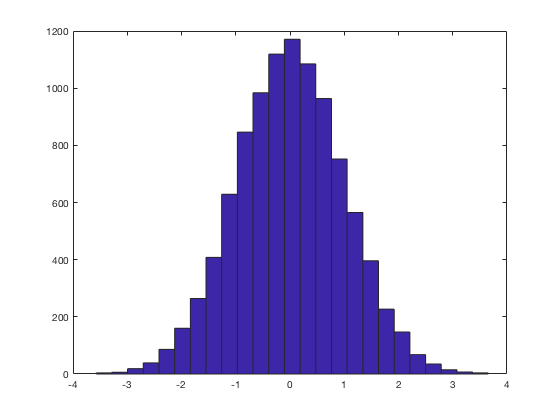

rnd_x = randn(1e+4,1);
figure 
hist(rnd_x,25)

(Figure 3.2: Histogram with random variable x, divided into 25 bins)

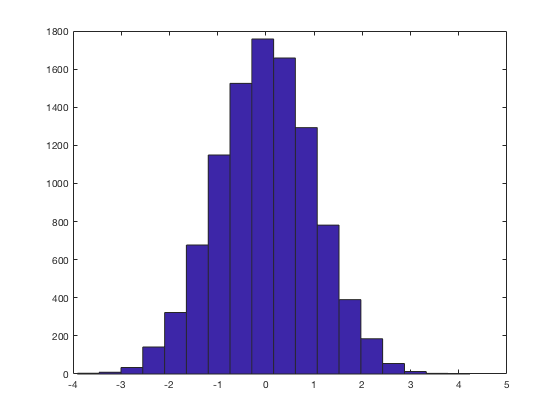

rnd_x = randn(1e+4,1);
figure 
hist(rnd_x,18)

(Figure 3.3: Histogram with random variable x, divided into 18 bins)

4.

The following figures depict three trigonometric functions using the same angle alpha, converted into radians. 

The hold on/hold off command is used to ensure that all three functions are plotted together on the same figure. Without this function, if only one figure is created, it will just plot the last function, overriding the previous two. 

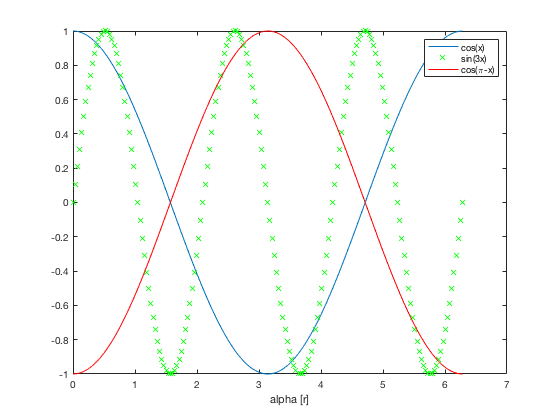

alpha = 0:2:360;
alpha = alpha.*pi/180;
figure
plot(alpha,cos(alpha))
hold on
plot(alpha,sin(3*alpha),'gx')
plot(alpha,cos(pi-alpha),'r-')
hold off
%legend(['cosine';'sine3a';'cospma'])
my_cell = {'cos(x)' 'sin(3x)' 'cos(\pi-x)'};
xlabel('alpha [r]')
legend(my_cell)

(Figure 4.1: Three trigonometric functions plotted in one chart)

5.

The following plots depict the output of various Matlab commands that can be used to create plots of varying scales. 

In addition to the standard plot function, semilogy and semilogx use a logarithmic scale for the y and x axis respectively, and loglog uses a logarithmic scale for botht he x and y axes. 

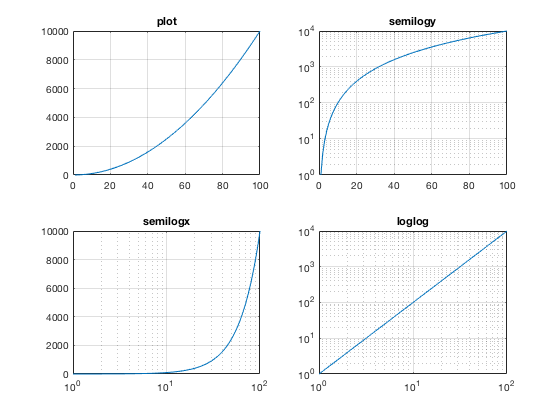

x=[];
y=[];
x = 1:100;
y = x.^2;
figure
subplot(2,2,1), plot(x,y), grid, title('plot')
subplot(2,2,2), semilogy(x,y), grid, title('semilogy')
subplot(2,2,3), semilogx(x,y), grid, title('semilogx')
subplot(2,2,4), loglog(x,y), grid, title('loglog')

(Figure 5.1: Four plots depicting different scales for the axes)

6. 

The following plots depict different visualizations. 

Pcolor creates a pseudocolor plot that results in a 2D surface plot with the peaks and valleys of the values being depicted with colors on the opposite ends of the color spectrum.

The contour function creates a contour plot.

Mesh creates a 3d mesh surface with the colors of the endges in the surface being defined by the Z value. 

Surf is similar to mesh, but the edge color is black and the face colors represent the Z value. 

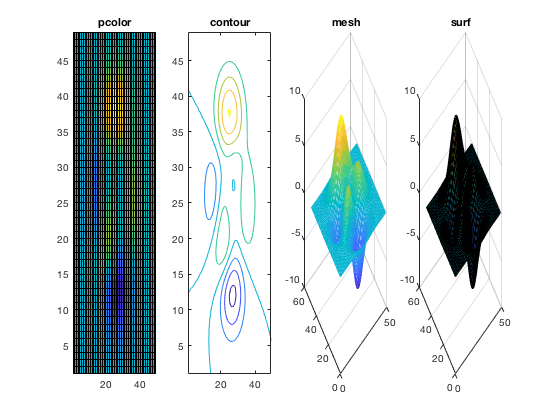

P = peaks;
figure
subplot(1,4,1), pcolor(P),title('pcolor')
subplot(1,4,2), contour(P), title('contour')
subplot(1,4,3),mesh(P),title('mesh')
subplot(1,4,4), surf(P), title('surf')

(Figure 6.1: Visualization of matrix P through four Matlab functions)